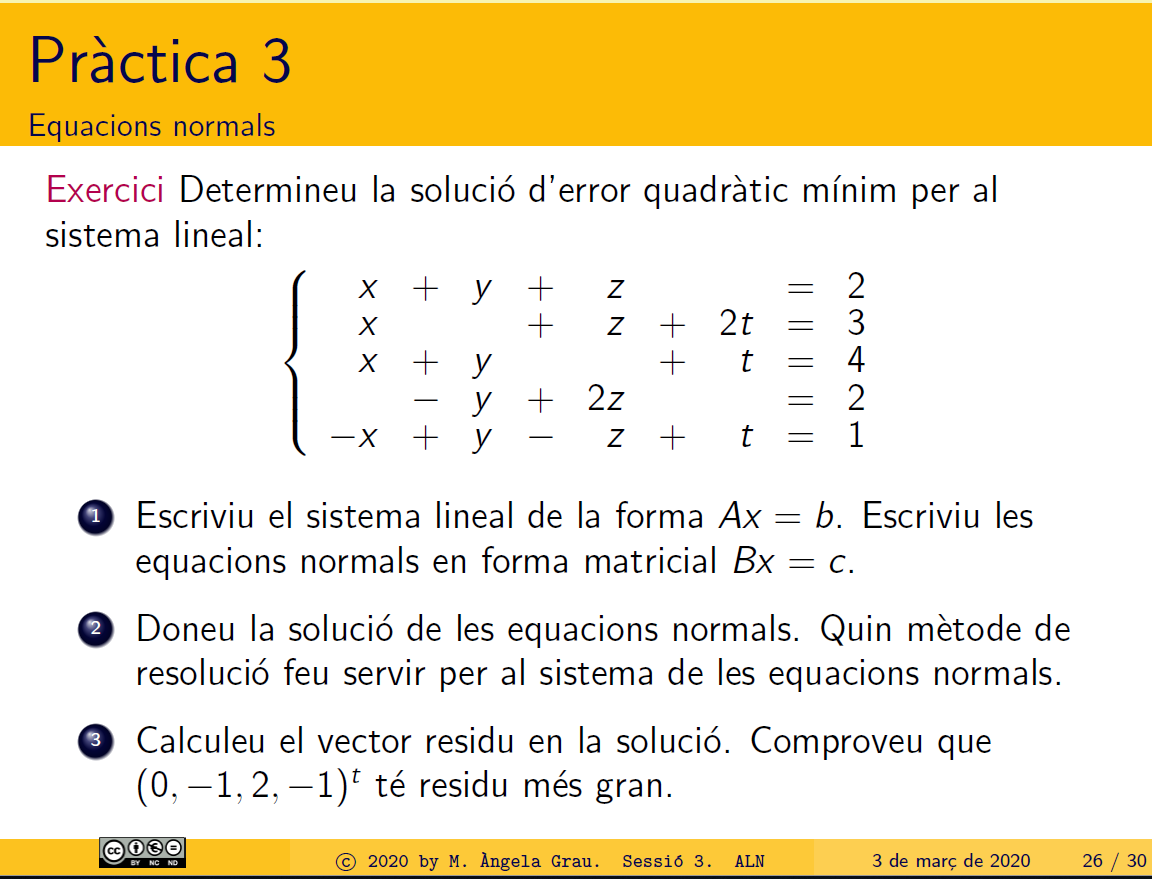

A = [1 1 1 0; 1 0 1 2; 1 1 0 1; 0 -1 2 0; -1 1 -1 1];
b = [2 3 4 2 1]';
x = A \b

x =       0.14286
       1.2857
       1.2857
       1.1429


Equacions normals (proyeccio ortogonal)

%r = b-Ax
%A'.r = 0
%A'(b-Ax) = 0
%A'b = A'Ax
x = (A'*A)\(A'*b)

x =       0.14286
       1.2857
       1.2857
       1.1429



%Exercici 3
r = b-A*x

r =      -0.71429
     -0.71429
       1.4286
      0.71429
  -2.2204e-16


norma2 = norm(b-A*x);
r2 = b-A*[0, -1, 2 -1]'

r2 =      1
     3
     6
    -3
     5


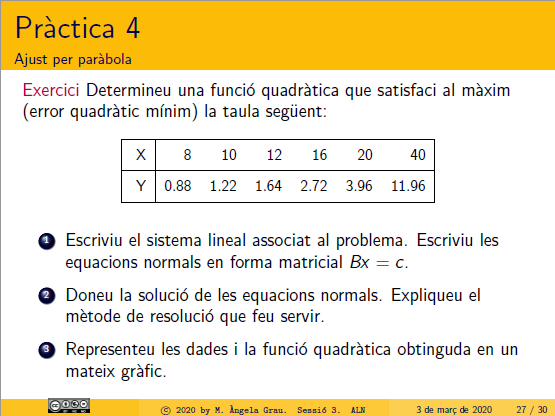

%p(t) = at^2 + bt + c 
B = [8^2 8 1; 10^2 10 1; 12^2 12 1; 16^2 16 1; 20^2 20 1; 40^2 40 1];
c = [0.88 1.22 1.64 2.72 3.96 11.96]';
x = B\ c;
polyval(x,c);
z = [8:40];
plot(z,polyval(x,z))
hold on
x2 = [ 8 10 12 16 20 40]'

x2 =      8
    10
    12
    16
    20
    40


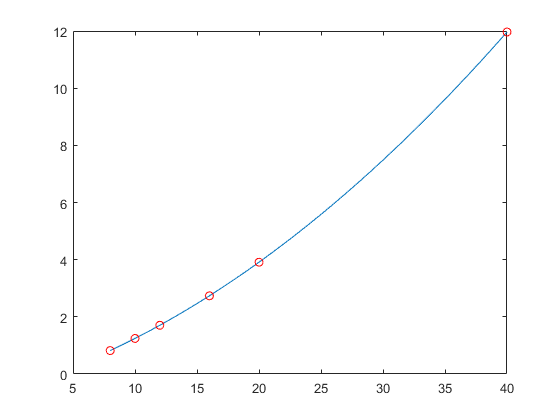

plot(x2,polyval(x,x2), 'ro')

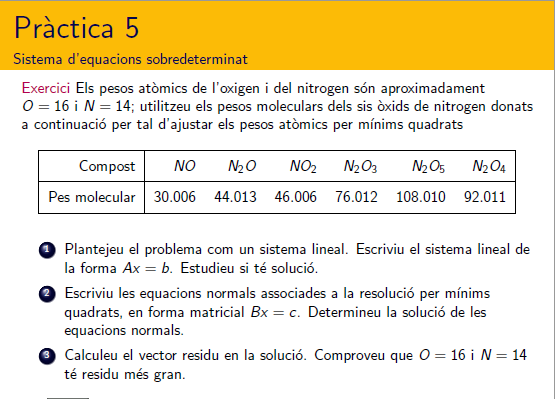

O = 16;
N = 14;
A = [1 1; 2 1; 1 2; 2 3; 2 5; 2 4]

A =      1     1
     2     1
     1     2
     2     3
     2     5
     2     4


p = [30.006 44.013 46.006 76.012 108.010 92.011]'

p =        30.006
       44.013
       46.006
       76.012
       108.01
       92.011


x =  A \ p

x =        14.007
       15.999


r = p-A*x

r =   -0.00020958
  -0.00012575
   0.00049701
   0.00028743
   -0.0002994
   -5.988e-06


r2 = p-A*[14 16]'

r2 =         0.006
        0.013
        0.006
        0.012
         0.01
        0.011


norm(r)

ans =    0.00069213


norm(r2)

ans =      0.024617


# Metodes Iteratirus

%A = E + D +F
%E diagonal inferior matriz
%D diagonal matriz
%F diagonal superior
%x^(k+1) = B(x^k)+c

## Jacobi

%B = -D^-1 (E+F)
%c = D^-1b

## Gauss-Seidel 

%B = (-(D+E)^-1)F
%c = ((D+E)^-1)b

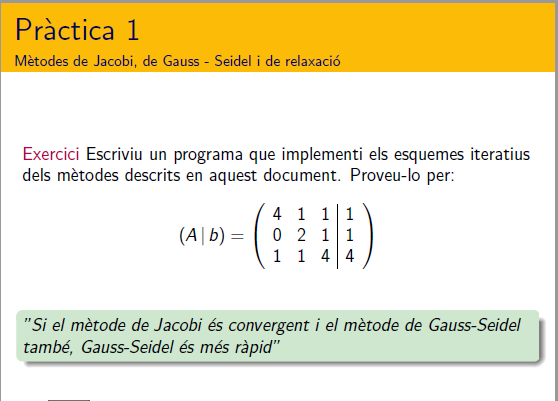

A = [4 1 1; 0 2 1; 1 1 4]

A =      4     1     1
     0     2     1
     1     1     4


b = [1 1 4]'

b =      1
     1
     4


D = diag(diag(A))

D =      4     0     0
     0     2     0
     0     0     4


E = tril(A,-1)

E =      0     0     0
     0     0     0
     1     1     0


F = triu(A,1)

F =      0     1     1
     0     0     1
     0     0     0


# **Jacobi**

format short G
Bj = (-D^-1)*(E+F)

Bj =             0        -0.25        -0.25
            0            0         -0.5
        -0.25        -0.25            0


c = (D^-1)*b

c =          0.25
          0.5
            1


x = zeros(size(b));
for i = 1:10
    x = Bj*x+c;
    r(i,1)=norm(A*x-b,1);
end
x

x =   -0.00043678
  -0.00042725
      0.99956


# **Gauss Seidel**

Bg = (-(D+E)^-1)*F

Bg =             0        -0.25        -0.25
            0            0         -0.5
            0       0.0625       0.1875


c = ((D+E)^-1)*b

c =          0.25
          0.5
       0.8125


x = zeros(size(b));
for i = 1:10
    x = Bg*x+c;
    r(i,2)=norm(A*x-b,1);
end
x

x =   -7.5805e-08
  -6.3541e-08
            1


r

r =          3.25        2.125
         1.75      0.40625
      0.79688     0.091797
      0.42969     0.012604
       0.2041    0.0020218
      0.10547   0.00052023
     0.051697   7.3619e-05
     0.026154   9.8143e-06
     0.012989    2.914e-06
    0.0065193   4.2417e-07


**Convergencia?**

rhoJ = max(abs(eig(Bj)))

rhoJ =           0.5


rhoG = max(abs(eig(Bg)))

rhoG =       0.17678


if (rhoJ >= 1 )
    display('metode de JACOBI divergent');
end
if (rhoG >= 1)
    display('metode de GAUSS SEIDEL divergent');
end

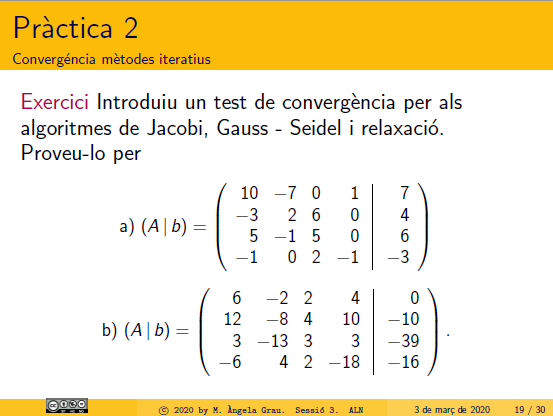

A = [10 -7 0 1; -3 2 6 0; 5 -1 5 0;-1 0 2 -1]

A =     10    -7     0     1
    -3     2     6     0
     5    -1     5     0
    -1     0     2    -1


b = [7 4 6 -3]'

b =      7
     4
     6
    -3


D = diag(diag(A))

D =     10     0     0     0
     0     2     0     0
     0     0     5     0
     0     0     0    -1


E = tril(A,-1)

E =      0     0     0     0
    -3     0     0     0
     5    -1     0     0
    -1     0     2     0


F = triu(A,1)

F =      0    -7     0     1
     0     0     6     0
     0     0     0     0
     0     0     0     0


**Convergencia?**

Bj = inv(D)*(E+F)

Bj =             0         -0.7            0          0.1
         -1.5            0            3            0
            1         -0.2            0            0
            1            0           -2            0


Bg = inv(D+E)*F

Bg =             0         -0.7            0          0.1
            0        -1.05            3         0.15
            0         0.49          0.6        -0.07
            0         1.68          1.2        -0.24


rhoJ = max(abs(eig(Bj)))

rhoJ =        1.4584


rhoG = max(abs(eig(Bg)))

rhoG =        1.8546


if (rhoJ >= 1 )
    display('metode de JACOBI divergent');
end

metode de JACOBI divergent


if (rhoG >= 1)
    display('metode de GAUSS SEIDEL divergent');
end

metode de GAUSS SEIDEL divergent


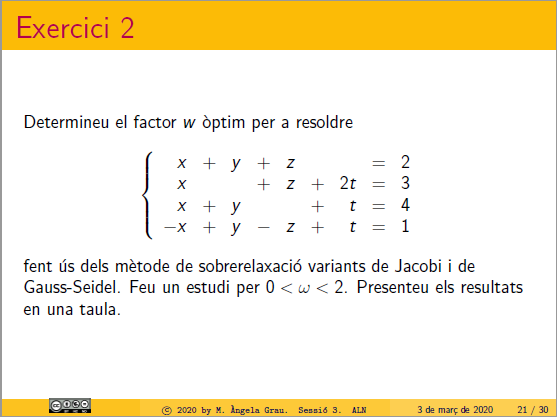

A = [4 1 1; 0 2 1; 1 1 4]

A =      4     1     1
     0     2     1
     1     1     4


b = [1 1 4]'

b =      1
     1
     4


w = 0:0.2:2;
n = length(w);
D = diag(diag(A))

D =      4     0     0
     0     2     0
     0     0     4


d = diag(1 ./diag(A))

d =          0.25            0            0
            0          0.5            0
            0            0         0.25


E = tril(A,-1)

E =      0     0     0
     0     0     0
     1     1     0


F = triu(A,1)

F =      0     1     1
     0     0     1
     0     0     0


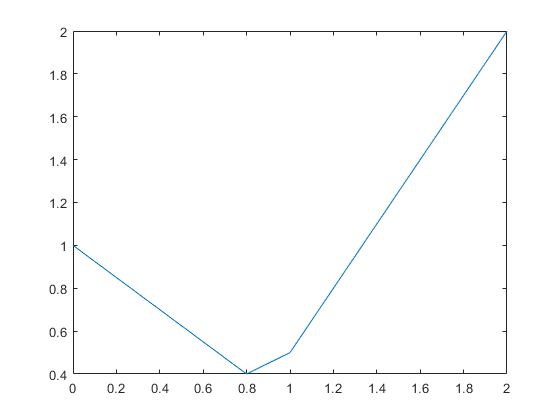

for k = 1:n
    Bwj = d*((1-w(k))*D-w(k)*(E+F));
    rhoWJ(k) = max(abs(eig(Bwj)));
end
figure
plot(w,rhoWJ)